Rivoluzione di un solido

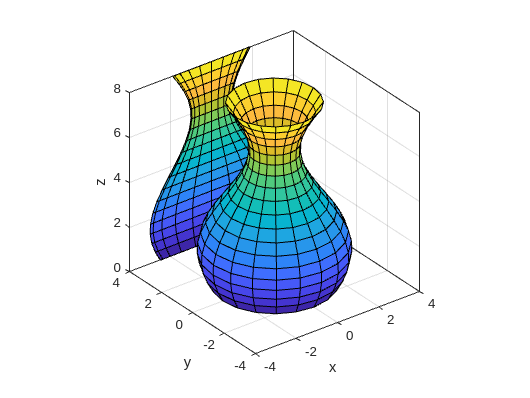

    t=(-pi/3:pi/10:2*pi-pi/2)';
    y=2+cos(t);
    [X,Y,Z]=cylinder(y); Z=8*Z;
    figure(1); surf(X,Y,Z); axis equal
    box on; hold on
    AX=[-4 4 -4 4 0 8]; axis(AX)
    xlabel('x'); ylabel('y'); zlabel('z')
    
    %disp([X,Y,Z])
    
    P_xz = [1 0 0; 0 0 0; 0 0 1];
    XYZ = [X(:), Y(:), Z(:)]';
    projected_XYZ=P_xz*XYZ;
    X_projected = reshape(projected_XYZ(1, :), size(X));
    Y_projected = reshape(projected_XYZ(2, :), size(Y));
    Z_projected = reshape(projected_XYZ(3, :), size(Z));
    surf(X_projected, Y_projected+4, Z_projected);
    AX=[-4 4 -4 4 0 8]; axis(AX)
    hold off;

Compute a generalized inverse of

A=\matrix{4 & 4 & -2 \\ 4 & 4 & -2 \\ -2 & -2 & 10}

A=[4 4 -2; 4 4 -2; -2 -2 10]

A =      4     4    -2
     4     4    -2
    -2    -2    10


[m,n]=size(A)

m = 3

n = 3

r=rank(A) %rank is < than m,n

r = 2

[~,pCol]=rref(A)

pCol =      1     3


[~,pRow]=rref(A')

pRow =      1     3


AA=[A(:,pCol) A(:,setdiff((1:n),pCol))]

AA =      4    -2     4
     4    -2     4
    -2    10    -2


AAA=[AA(:,pRow) AA(:,setdiff((1:m),pRow))]

AAA =      4     4    -2
     4     4    -2
    -2    -2    10



% E quindi?

[~,pCOL]=rref(A);
Pcol=eye(n); %Identity matrix
Pcol=[Pcol(:,pCOL) Pcol(:,setdiff((1:n),pCOL))] %Cols permutation matrix

Pcol =      1     0     0
     0     0     1
     0     1     0



[~,pROW]=rref(A')

pROW =      1     3


Prow=eye(m);
Prow=[Prow(pROW,:);Prow(setdiff((1:m),pROW),:)] %Row permutation matrix

Prow =      1     0     0
     0     0     1
     0     1     0



PAP=Prow*A*Pcol

PAP =      4    -2     4
    -2    10    -2
     4    -2     4


Ar=PAP(1:r,1:r)

Ar =      4    -2
    -2    10


G=[inv(Ar) zeros(r,m-r); zeros(n-r,m)]

G =     0.2778    0.0556         0
    0.0556    0.1111         0
         0         0         0


ans =      4     4    -2
     4     4    -2
    -2    -2    10


all(all(A* (Pcol*G*Prow) *A == A))

ans = logical
   1


function G = generalizedInverse(A)
    % Computes the generalized inverse G of the matrix A such that A*G*A = A
    
    % Step 1: Perform Singular Value Decomposition (SVD)
    [U, S, V] = svd(A);
    
    % Step 2: Compute the pseudoinverse of the diagonal matrix S
    % The pseudoinverse of S is obtained by taking the reciprocal of the non-zero elements
    % and leaving the zeros as they are (this is the generalized inverse of S).
    
    % Create an empty matrix for S+
    S_inv = zeros(size(S'));
    
    % Compute the pseudoinverse of the diagonal matrix S
    for i = 1:min(size(S))
        if S(i, i) > 1e-12  % Use a tolerance to avoid division by very small values
            S_inv(i, i) = 1 / S(i, i);
        end
    end
    
    % Step 3: Construct the generalized inverse G
    G = V * S_inv * U';
end

A=randi([-3 4],3,3)

A =      0     3    -3
     2    -1    -3
     3     1    -2


G=generalizedInverse(A)

G =    -0.1667   -0.1000    0.4000
    0.1667   -0.3000    0.2000
   -0.1667   -0.3000    0.2000


int8(A*G*A) == A

ans = 3×3 logical array
   1   1   1
   1   1   1
   1   1   1
